clc, clear all
%%plot stuff
beta = 0.2;
diam = 0.235;
Npts = 10;
t_max = 3.2 / beta;
T = linspace(0, t_max, t_max*Npts);
U = T .* beta;
R = 4.*[0.3960*cos(2.65*(U+1.4)) ; -0.99*sin(U+1.4)];
clf
hold on
plot(R(1,:), R(2,:),'k--', "Linewidth", 2)
%plot(R(1,:), R(2,:),'.', "Markersize", 10)
%%symbolic matlab to find other stuff


syms t

ri=4*0.3960*cos(2.65*((t * beta)+1.4));
rj=4*-0.99*sin((t * beta)+1.4);
rk=0*t;
r=[ri,rj,rk];


v = diff(r, t);

T_hat = (v ./ norm(v));
dT_hat = diff(T_hat, t);
N_hat = (dT_hat ./ norm(dT_hat));


%%
for i = 1:2:16
    t = i
    T_hat_eval = eval(subs(T_hat));
    N_hat_eval = eval(subs(N_hat));
    quiver(R(1,t*Npts), R(2,t*Npts), T_hat_eval(1), T_hat_eval(2), "r", "Linewidth", 1)
    quiver(R(1,t*Npts), R(2,t*Npts), N_hat_eval(1), N_hat_eval(2), "b", "Linewidth", 1)
end

t = 1

t = 3

t = 5

t = 7

t = 9

t = 11

t = 13

t = 15

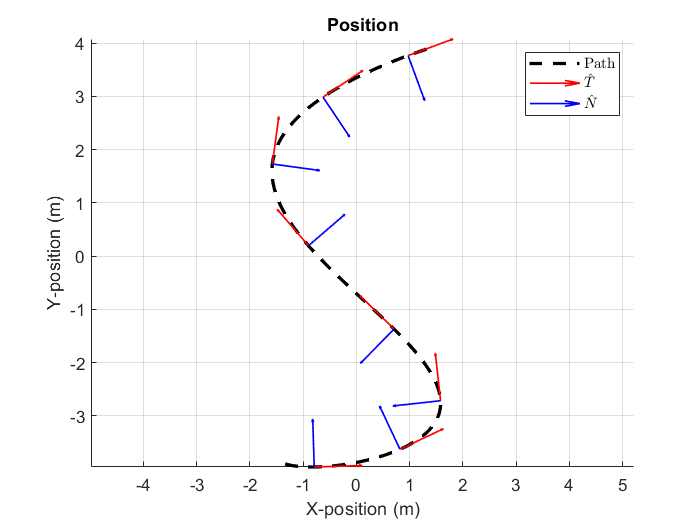

xlabel("X-position (m)")
ylabel("Y-position (m)")
title("Position")
legend("Path", '$$\hat{T}$$', '$$\hat{N}$$','Interpreter','Latex')
grid on
axis equal

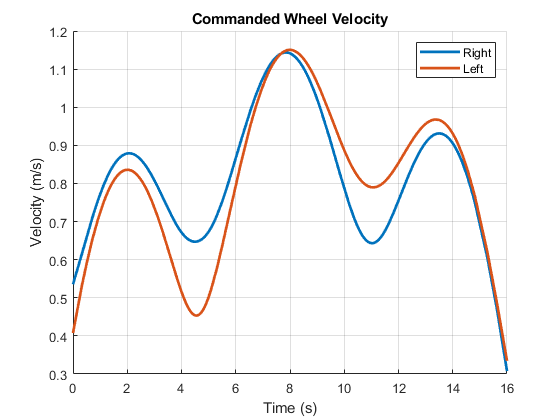


omega = cross(T_hat, dT_hat);

V_right = norm(v) + omega(3) .* (diam/2);
V_left = norm(v) - omega(3) .* (diam/2);


figure(2)
clf
hold on
fplot(V_right, [0,16], "Linewidth", 2)
fplot(V_left, [0,16], "Linewidth", 2)
title("Commanded Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off
legend("Right", "Left")

grid on

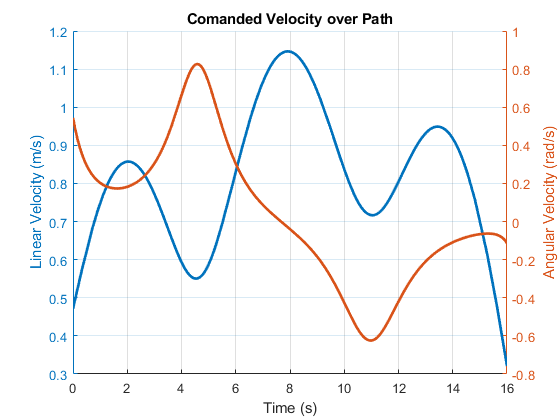

figure()
clf
hold on
title("Comanded Velocity over Path")
yyaxis left
fplot(norm(v), [0,16], "Linewidth", 2)
ylabel("Linear Velocity (m/s)")
yyaxis right
fplot(omega(3), [0,16], "Linewidth", 2)
ylabel("Angular Velocity (rad/s)")
xlabel("Time (s)")

grid on

hold off

figure()
clf
data = readtable("BoD_data")

data = 292×3 table
    time_seconds_    encoderLeft_meters_    encoderRight_meters_
    _____________    ___________________    ____________________

        102.3              18.743                   18.37       
        102.4              18.776                    18.4       
        102.5              18.809                   18.43       
        102.6              18.842                   18.46       
        102.7              18.875                  18.491       
        102.8              18.908                  18.521       
        102.9              18.941                  18.551       
          103              18.974                  18.581       
        103.1              19.007                  18.611       
        103.2               19.04                  18.642       
        103.3              19.073                  18.672       
        103.4              19.106

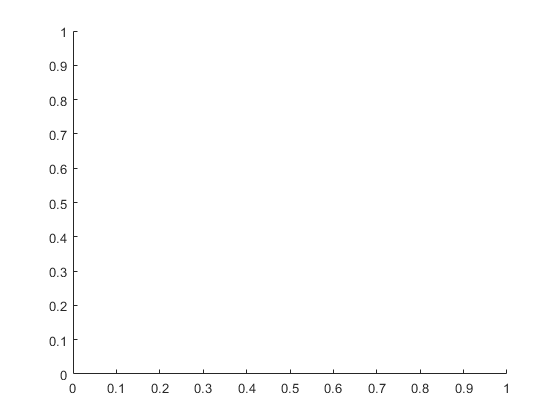


hold on

reconstructed_pos = [-1.33493 -3.90238, 0];
reconstructed_vel = [0,0];
theta =0;

acos(dot(eval(subs(T_hat, t, 0)), [1 0 0]))

ans = 0.3529



for (i = 2:length(data.time_seconds_))
    dt = data.time_seconds_(i) - data.time_seconds_(i-1);
    ddl = data.encoderLeft_meters_(i) - data.encoderLeft_meters_(i-1);
    ddr = data.encoderRight_meters_(i) - data.encoderRight_meters_(i-1);
    
    
    vl = ddl/dt;
    vr = ddr/dt;
    
    reconstructed_vel(end+1, :) = [vl, vr];
    lin_vel = (vl + vr) / 2;
    
    omega = (vr - vl) / diam;

    
    reconstructed_pos(end + 1, :) = reconstructed_pos(end, :) + (lin_vel .* eval(subs(T_hat, t, data.time_seconds_(i) - data.time_seconds_(1)))) * dt;
    
end

Unable to resolve the name data.time_seconds_.


plot(reconstructed_pos(:,1), reconstructed_pos(:,2))

%clf
%hold on
%plot(reconstructed_vel(:,1))
%plot(reconstructed_vel(:,2))
%hold off
rt = [0 0];
allrt = [0 0];
theta = 0;
for i = 2:length(data.time_seconds_)
    dt = data.time_seconds_(i) - data.time_seconds_(i-1);
    ddl = data.encoderLeft_meters_(i) - data.encoderLeft_meters_(i-1);
    ddr = data.encoderRight_meters_(i) - data.encoderRight_meters_(i-1);
    
    vl = ddl/dt;
    vr = ddr/dt;
    
    V = vl+vr/2;
    Omega = vr-vl/diam;
    theta = theta + Omega*dt;
    rtx = V*cos(theta)*dt;
    rty = V*sin(theta)*dt;
    rt = rt + [rtx rty];
    allrt = [allrt; rt];
end

Unable to resolve the name data.time_seconds_.

plot(allrt(:, 1), allrt(:, 2))